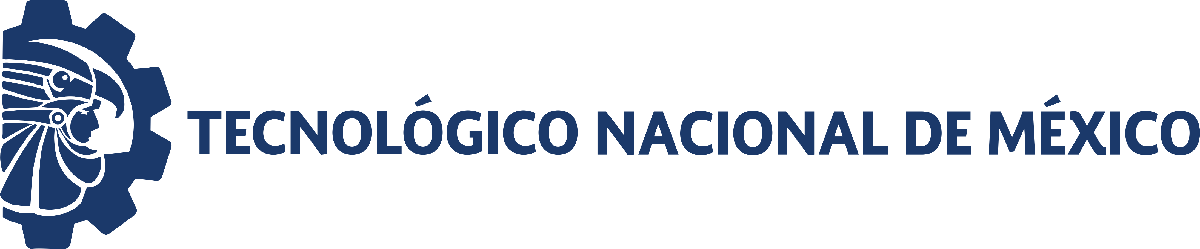                                 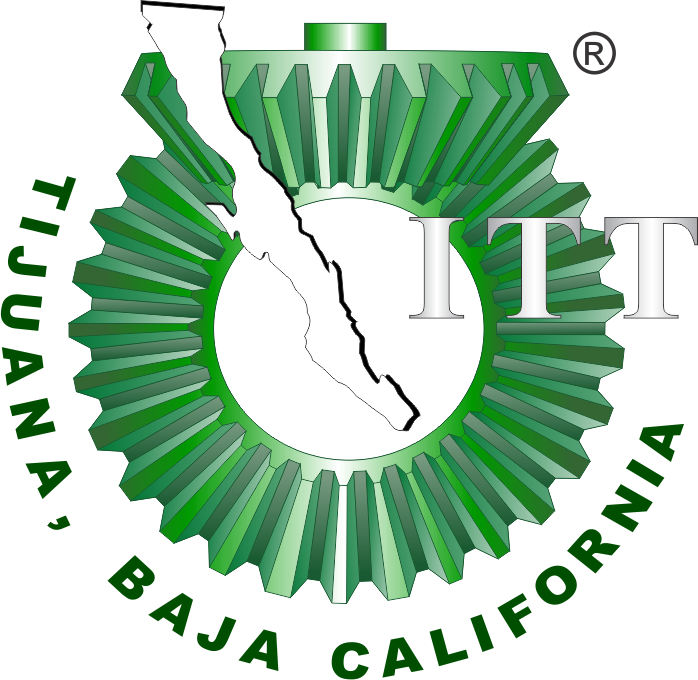

# Final Project

**Departamento de Ingeniería Eléctrica y Electrónica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## General Information

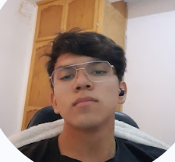

Nombre del alumno: **Chaparro Zamora Alain Yahir**

Número de control: **21212147**

Correo institucional: **l21212147@tectijuana.edu.mx**

Carrera:** Ingenieria Biomedica**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

**Objetive: **To integrate specific competencies related to the modeling, analysis, and control of biological systems, in order to illustrate and predict their dynamics in both the short and long term. The goal is to lay the groundwork for the development of digital twins capable of addressing and solving problems within the field of Systems Biology.

## Simulation Data

clc; clear; close all; warning('off', 'all');
filename = 'data.csv';
sys = readmatrix(filename);
t = sys(:,1); 
x = sys(:,2);  
y = sys(:,3); 
z = sys(:,4);
T = array2table([t, x, y, z], 'VariableNames', {'tiempo (days)', 'x', 'y', 'z'});
disp(T);

    tiempo (days)      x        y         z  
    _____________    _____    ______    _____

          0          0.517    19.939    0.281
          7           0.58    19.578    0.609
         14          0.726    18.678    1.063
         21          0.965    16.215    1.758
         28          1.282    14.005    2.752
         35          1.825    11.467    3.975
         42          2.473     8.096    4.895
         49          2.974     4.327    6.096
         56           3.43     1.287    7.152
         63          3.717     0.194    7.328
         70          3.829      0.56    7.232



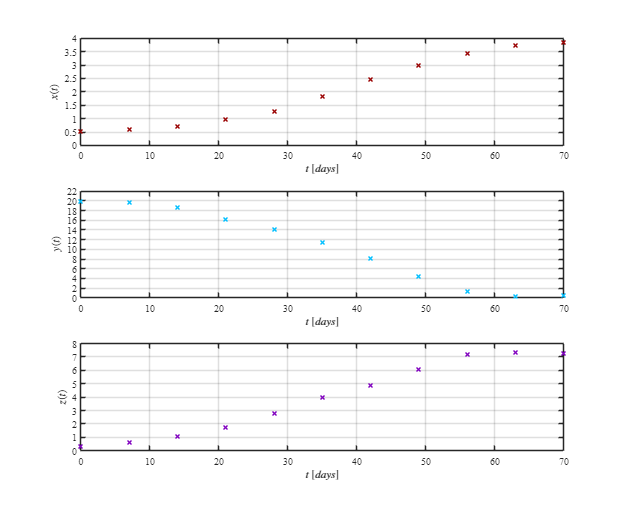

plotdata(t, x, y, z);

## Smooth Data

Data smoothed exported as: "data_fit.csv".


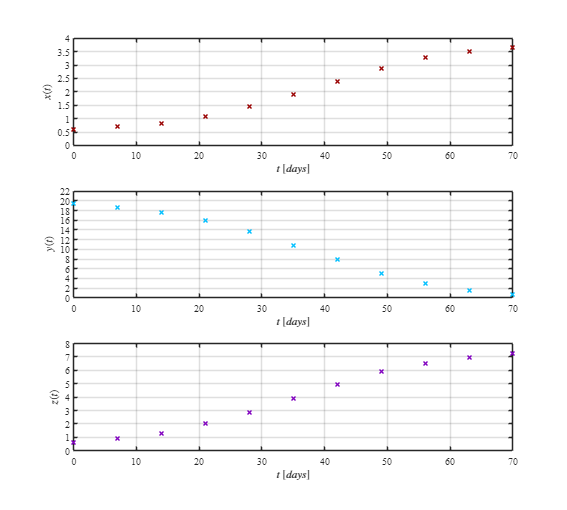

clc; clear; close all; warning('off','all')
filename = 'Data.csv';
sys = readmatrix(filename);
t= sys(:,1);
x= sys(:,2);
y= sys(:,3);
z= sys(:,4);
plotDataS(t, x, y, z);

## Nonlinear Regression

The equations considered for tthe approach of the model are the following:

##  

##  

##  


Sample size (n): 11
Parameters to be estimated: 6
Degrees of freedom: 27
R-squared: 0.9998
Corrected AIC: -65.2787

    Param     Estimate         SE           MoE                  CI95                pValue  
    _____    __________    __________    __________    ________________________    __________

    "p1"      0.0006015    9.2161e-05     0.0001891    0.00041241     0.0007906    5.3482e-07
    "p2"     0.00072444    3.8939e-05    7.9896e-05    0.00064454    0.00080434    6.3191e-17
    "p3"       0.014804    0.00042563    0.00087331      0.013931      0.015677    5.8103e-24
    "p4"       0.030033    0.00055695     0.0011428       0.02889      0.031176     4.956e-29
    "p5"      0.0040202    0.00067335     0.0013816     0.0026386     0.0054018    2.2873e-06
    "p6"      0.0029

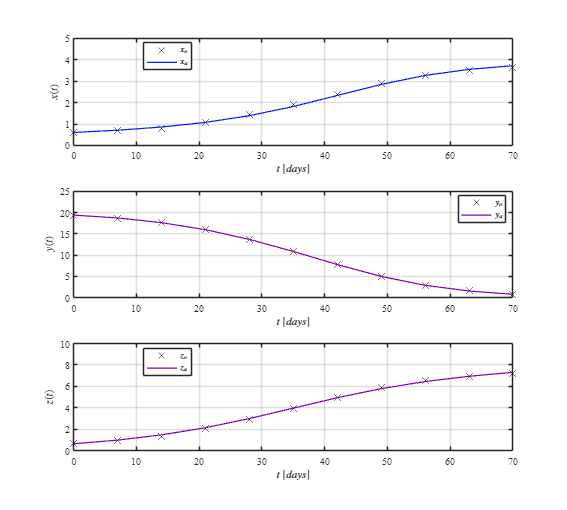

warning('off')
sys = readmatrix('data_fit.csv');
t = sys(:,1);
x = sys(:,2);
y = sys(:,3);
z = sys(:,4);
P0 = [0.0012; 0.00055; 0.013; 0.028; 0.0020; 0.0033];
[mdl, xa, ya, za] = Varied(t, x, y, z, P0);

## Jacobian Matrix

clear; close all; clc
syms x y z p1 p2 p3 p4 p5 p6 real
dx = p1*x*y + p2*x*y*z;
dy = p3*y - p4*x*y;
dz = p5*z + p6*y*z;
J = jacobian([dx, dy, dz], [x, y, z]);
disp('Jacobian matrix of the system:'); disp(J);

Jacobian matrix of the system:


$$\left(\begin{array}{ccc} p_{1}\,y+p_{2}\,y\,z & p_{1}\,x+p_{2}\,x\,z & p_{2}\,x\,y\\ -p_{4}\,y & p_{3}-p_{4}\,x & 0\\ 0 & p_{6}\,z & p_{5}+p_{6}\,y \end{array}\right)$$

## Equilibrium points

clear; close all; clc
syms x y z p1 p2 p3 p4 p5 p6 real
dx = p1*x*y + p2*x*y*z;
dy = p3*y - p4*x*y;
dz = p5*z + p6*y*z;
eq1 = dx == 0;
eq2 = dy == 0;
eq3 = dz == 0;
edos = solve([eq1, eq2, eq3], [x, y, z], 'Real', true);
n = length(edos.x);
fprintf('The system has %d equilibrium point(s).\n\n', n);

The system has 2 equilibrium point(s).



for i = 1:min(2,n)
fprintf('Equilibrium point %d:\n', i);
fprintf('x = %s\n', char(edos.x(i)));
fprintf('y = %s\n', char(edos.y(i)));
fprintf('z = %s\n\n', char(edos.z(i)));
end

Equilibrium point 1:


x = 0


y = 0


z = 0



Equilibrium point 2:


x = p3/p4


y = -p5/p6


z = -p1/p2



## 2tMax

warning('off')
sys = readmatrix('data_fit.csv');
t = sys(:,1);
x = sys(:,2);
y = sys(:,3);
z = sys(:,4);
P0 = [0.0012; 0.00055; 0.013; 0.028; 0.0020; 0.0033];
[mdl, xa, ya, za, t_ext, x_ext, y_ext, z_ext] = VariedExtended(t, x, y, z, P0);


[EXTENDED] Sample size (n): 11
Parameters to be estimated: 6
Degrees of freedom: 27
R-squared: 0.9998
Corrected AIC: -65.2787

    Param     Estimate         SE           MoE                  CI95                pValue  
    _____    __________    __________    __________    ________________________    __________

    "p1"      0.0006015    9.2161e-05     0.0001891    0.00041241     0.0007906    5.3482e-07
    "p2"     0.00072444    3.8939e-05    7.9896e-05    0.00064454    0.00080434    6.3191e-17
    "p3"       0.014804    0.00042563    0.00087331      0.013931      0.015677    5.8103e-24
    "p4"       0.030033    0.00055695     0.0011428       0.02889      0.031176     4.956e-29
    "p5"      0.0040202    0.00067335     0.0013816     0.0026386     0.0054018    2.2873e-06
    "p6" 

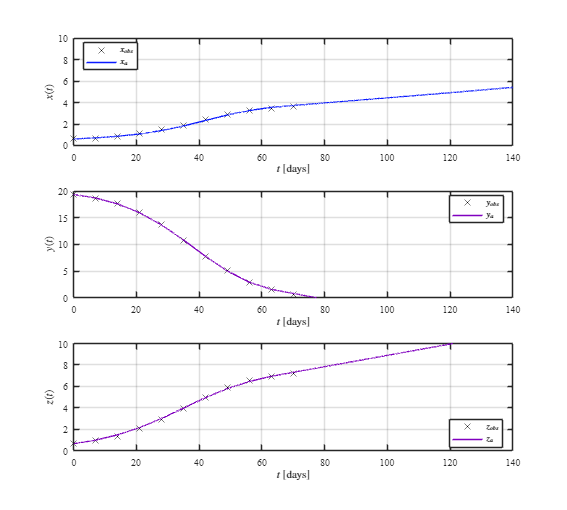

plot2t(t, x, y, z, t_ext, x_ext, y_ext, z_ext);

## **Representation**

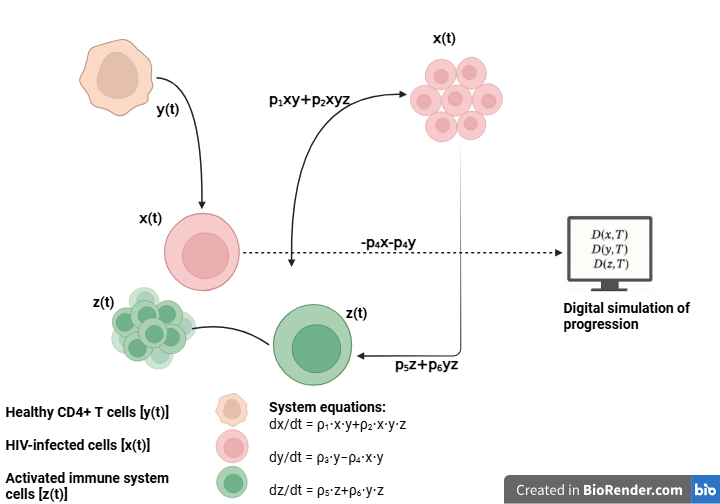

The diagram illustrates a dynamic model of HIV infection, developed from in vitro experimental data. The system is composed of three interacting immune cell populations:

- Normal Cells y(t): CD4+ T cells not yet infected.

- Infected Cells x(t): CD4+ T cells that have been infected.

- Immune System Cells z(t): Activated effector cells (e.g., CD8+ cytotoxic T lymphocytes).

Arrows between the cell types represent biological interactions expressed through nonlinear mathematical terms formulated as differential equations. These expressions describe the rate of change of each population over time, using symbolic parameters ρ1 through ρ6, which represent different biological interaction rates.

For example:

- The infection process is modeled by the interaction term ρ1xy, and it is further influenced by the immune system through ρ2xyz.

- The immune response is described by the activation of immune cells via intrinsic growth (ρ5z) and stimulation by healthy cells (ρ6yz).

- The loss of healthy cells due to infection is modeled by the term -ρ4xy, while their natural proliferation is given by ρ3y.

On the right side, the diagram includes a digital twin simulation block, representing the system of differential equations:

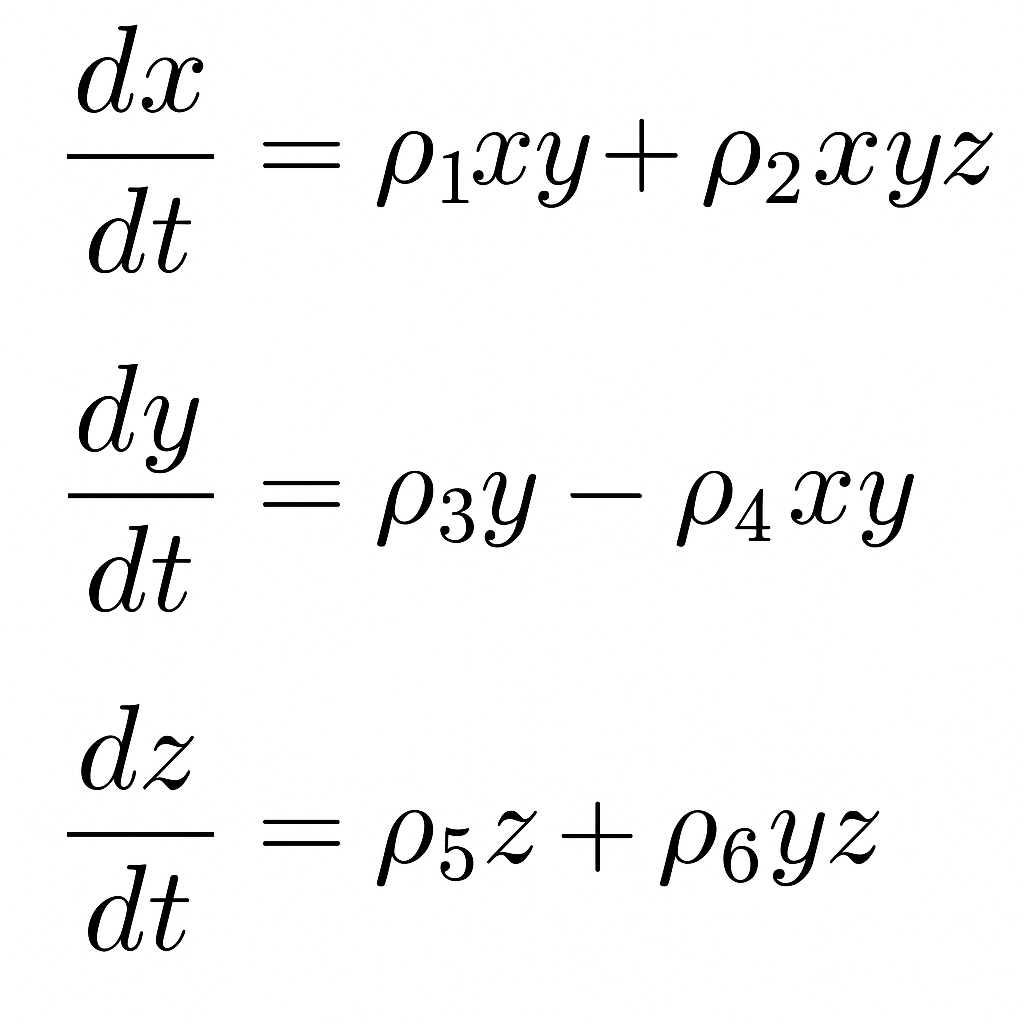

This simulation-based model enables the prediction of system dynamics over time and supports the exploration of long-term behavior and stability under controlled computational conditions, without requiring specific clinical assumptions.

## Conclussions

In this project, a nonlinear dynamic model was built, simulated, and analyzed with the aim of representing the behavior of a physiological system made up of three interrelated variables over time. The modeling process was drive by the data collected, relying exclusively on experimental time series collected over a specific period. The differential equations developed describe the temporal evolution of each variable, incorporating six parameters that represent the interactions between them. These parameters were estimated through nonlinear regression, using a smoothed version of the original dataset to minimize measurement noise and discontinuities.

One of the most notable outcomes of the model fitting was the coefficient of determination (R² = 0.9998), which shows that the system of equations closely matches the observed data. The corrected Akaike Information Criterion (AICc = –65.28) also supports the adequacy of the model's structure, achieving a balance between the quality of fit and model complexity. All six estimated parameters were statistically significant, with p-values close to zero and narrow confidence intervals, indicating that each one contributes meaningfully to the system’s dynamics. Moreover, the model does not include redundant or unnecessary terms, which is essential for both interpretation and potential generalization.

The Jacobian matrix analysis provided useful insights into the system’s local sensitivity and the interdependence among variables. Two equilibrium points were identified, including a non-trivial fixed point with non-zero values, suggesting that the system tends toward stability under certain conditions. These equilibrium states help characterize long-term behavior and could serve as a basis for future stability studies or control strategies.

Also was implemente an differente apprach for the work (2t model), in which the system's behavior was projected over a time span twice as long as the original dataset. The results of this extension showed that the model remains stable and consistent outside the initial data range. No abrupt divergences or unrealistic trends were observed, supporting the idea that the model is not only descriptive but also predictive within a reasonable timeframe. Lastly, visual comparisons between the observed data, the smoothed data, and the simulated outputs confirmed that the model effectively follows the expected trajectories, capturing key features such as exponential growth, decay, saturation, or delayed responses between variables.

## Function

## Raw data plot

function plotdata(t, x, y, z)
    c1 = [0.60, 0.00, 0.00];  
    c2 = [0.00, 0.75, 1.00];  
    c3 = [0.50, 0.00, 0.75]; +
    fig = figure('Color', 'w', 'Units', 'Centimeters', 'Position', [2, 2, 22, 18]);

    subplot(3,1,1);
    plot(t, x, 'x', 'LineWidth', 1.5, 'Color', c1, 'DisplayName', '$x_1(t)$');
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    xlabel('$t$ $[days]$', 'Interpreter', 'latex');
    ylabel('$x(t)$', 'Interpreter', 'latex');
    xlim([0 70]); xticks(0:10:70);
    ylim([0 4]); yticks(0:0.5:4);
    grid on;

    subplot(3,1,2);
    plot(t, y, 'x', 'LineWidth', 1.5, 'Color', c2, 'DisplayName', '$y_1(t)$');
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    xlabel('$t$ $[days]$', 'Interpreter', 'latex');
    ylabel('$y(t)$', 'Interpreter', 'latex');
    xlim([0 70]); xticks(0:10:70);
    ylim([0 22]); yticks(0:2:22);
    grid on;

    subplot(3,1,3);
    plot(t, z, 'x', 'LineWidth', 1.5, 'Color', c3, 'DisplayName', '$z_1(t)$');
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    xlabel('$t$ $[days]$', 'Interpreter', 'latex');
    ylabel('$z(t)$', 'Interpreter', 'latex');
    xlim([0 70]); xticks(0:10:70);
    ylim([0 8]); yticks(0:1:8);
    grid on;
    print(fig, 'RawData', '-dpdf', '-bestfit');
end



## Smooth data plot

function plotDataS(t, x, y, z)
    c1 = [0.60, 0.00, 0.00];  
    c2 = [0.00, 0.75, 1.00];  
    c3 = [0.50, 0.00, 0.75]; 
    x_s = smoothdata(x, 'movmean', 5);
    y_s = smoothdata(y, 'movmean', 5);
    z_s = smoothdata(z, 'movmean', 5);
    fig = figure('Color', 'w', 'Units', 'Centimeters', 'Position', [2, 5, 20, 18]);
    tmax = 70;

    subplot(3,1,1);
    plot(t, x_s, 'x', 'LineWidth', 1.5, 'Color', c1, 'DisplayName', '$x_1(t)$');
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    xlabel('$t$ $[days]$', 'Interpreter', 'latex');
    ylabel('$x(t)$', 'Interpreter', 'latex');
    xlim([0 tmax]); xticks(0:10:tmax);
    ylim([0 4]); yticks(0:0.5:4);
    grid on;

    subplot(3,1,2);
    plot(t, y_s, 'x', 'LineWidth', 1.5, 'Color', c2, 'DisplayName', '$y_1(t)$');
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    xlabel('$t$ $[days]$', 'Interpreter', 'latex');
    ylabel('$y(t)$', 'Interpreter', 'latex');
    xlim([0 tmax]); xticks(0:10:tmax);
    ylim([0 22]); yticks(0:2:22);
    grid on;

    subplot(3,1,3);
    plot(t, z_s, 'x', 'LineWidth', 1.5, 'Color', c3, 'DisplayName', '$z_1(t)$');
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    xlabel('$t$ $[days]$', 'Interpreter', 'latex');
    ylabel('$z(t)$', 'Interpreter', 'latex');
    xlim([0 tmax]); xticks(0:10:tmax);
    ylim([0 8]); yticks(0:1:8);
    grid on;
    datos_fit = table(t(:), x_s(:), y_s(:), z_s(:), ...
        'VariableNames', {'T', 'x', 'y', 'z'});
    writetable(datos_fit, 'data_fit.csv');
    disp('Data smoothed exported as: "data_fit.csv".');
    print(fig, 'DataSmooth', '-dpdf', '-bestfit');
end



## Nonlinear regression algorithm

function [mdl, xa, ya, za] = Varied(t, x, y, z, P0)
    x0 = x(1); y0 = y(1); z0 = z(1);

    t3 = [t; t; t];
    fo = [x; y; z];

    function fi = model(p, tvec)
        dt = 0.01;
        tmat = reshape(tvec, [], 3);
        t_local = tmat(:,1);
        time = (0:dt:max(t_local))';
        n = numel(time);

        x_sim = zeros(n,1); x_sim(1) = x0;
        y_sim = zeros(n,1); y_sim(1) = y0;
        z_sim = zeros(n,1); z_sim(1) = z0;

        for i = 1:n-1
            [dx, dy, dz] = f(x_sim(i), y_sim(i), z_sim(i), p);
            xp = x_sim(i) + dx*dt;
            yp = y_sim(i) + dy*dt;
            zp = z_sim(i) + dz*dt;
            [dxp, dyp, dzp] = f(xp, yp, zp, p);

            x_sim(i+1) = x_sim(i) + (dx + dxp)*dt/2;
            y_sim(i+1) = y_sim(i) + (dy + dyp)*dt/2;
            z_sim(i+1) = z_sim(i) + (dz + dzp)*dt/2;
        end

        xi = interp1(time, x_sim, t_local, 'linear', NaN);
        yi = interp1(time, y_sim, t_local, 'linear', NaN);
        zi = interp1(time, z_sim, t_local, 'linear', NaN);

        fi = [xi; yi; zi];
    end

    function [dx, dy, dz] = f(x, y, z, p)
        dx = p(1)*x*y + p(2)*x*y*z;
        dy = p(3)*y - p(4)*x*y;
        dz = p(5)*z + p(6)*y*z;
    end
    mdl = fitnlm(t3, fo, @model, P0);
    fa = mdl.Fitted;
    fn = reshape(fa, [], 3);
    xa = fn(:,1);
    ya = fn(:,2);
    za = fn(:,3);
    coef = mdl.Coefficients;
    Estimate = coef.Estimate;
    SE = coef.SE;
    pValue = coef.pValue;
    CI95 = coefCI(mdl, 0.05);
    dof = mdl.DFE;
    tval = tinv(0.975, dof);
    MoE = SE * tval;

    Params = ["p1"; "p2"; "p3"; "p4"; "p5"; "p6"];
    Results = table(Params, Estimate, SE, MoE, CI95, pValue, ...
        'VariableNames', {'Param','Estimate','SE','MoE','CI95','pValue'});

    fprintf('\nSample size (n): %d', numel(x));
    fprintf('\nParameters to be estimated: %d', numel(P0));
    fprintf('\nDegrees of freedom: %d', dof);
    fprintf('\nR-squared: %.4f', mdl.Rsquared.Ordinary);
    fprintf('\nCorrected AIC: %.4f\n\n', mdl.ModelCriterion.AICc);
    disp(Results);

    X_plot = [x, xa];
    Y_plot = [y, ya];
    Z_plot = [z, za];
    plotXYZResults(t, X_plot, Y_plot, Z_plot);
end




## Nonlinear regression plot

function plotXYZResults(t, x, y, z)
    negro  = [0.00, 0.00, 0.00];
    azul   = [0.04, 0.10, 1.00];
    morado = [0.50, 0.00, 0.75];
    tmax = 70;
    fig = figure('Color', 'w', 'Units', 'Centimeters', 'Position', [2, 5, 20, 18]);

    subplot(3,1,1);
    plot(t, x(:,1), 'x', 'Color', negro, 'MarkerSize', 10, 'DisplayName', '$x_{o}$');
    hold on;
    plot(t, x(:,2), '-', 'Color', azul, 'LineWidth', 1.2, 'DisplayName', '$x_{a}$');
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    xlabel('$t$ $[days]$', 'Interpreter', 'latex');
    ylabel('$x(t)$', 'Interpreter', 'latex');
    legend('Interpreter', 'latex', 'Location', 'best');
    xlim([0 tmax]); ylim([0 5]);
    xticks(0:10:tmax); yticks(0:1:5);
    grid on;

    subplot(3,1,2);
    plot(t, y(:,1), 'x', 'Color', negro, 'MarkerSize', 10, 'DisplayName', '$y_{o}$');
    hold on;
    plot(t, y(:,2), '-', 'Color', morado, 'LineWidth', 1.2, 'DisplayName', '$y_{a}$');
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    xlabel('$t$ $[days]$', 'Interpreter', 'latex');
    ylabel('$y(t)$', 'Interpreter', 'latex');
    legend('Interpreter', 'latex', 'Location', 'best');
    xlim([0 tmax]); ylim([0 25]);
    xticks(0:10:tmax); yticks(0:5:25);
    grid on;

    subplot(3,1,3);
    plot(t, z(:,1), 'x', 'Color', negro, 'MarkerSize', 10, 'DisplayName', '$z_{o}$');
    hold on;
    plot(t, z(:,2), '-', 'Color', morado, 'LineWidth', 1.2, 'DisplayName', '$z_{a}$');
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    xlabel('$t$ $[days]$', 'Interpreter', 'latex');
    ylabel('$z(t)$', 'Interpreter', 'latex');
    legend('Interpreter', 'latex', 'Location', 'best');
    xlim([0 tmax]); ylim([0 10]);
    xticks(0:10:tmax); yticks(0:2:10);
    grid on;
    print(fig, 'NonlinearRegression', '-dpdf', '-bestfit');
end




## 2T model

function [mdl, xa, ya, za, t_ext, x_ext, y_ext, z_ext] = VariedExtended(t, x, y, z, P0)
    x0 = x(1); y0 = y(1); z0 = z(1);
    t3 = [t; t; t];
    fo = [x; y; z];
    function fi = model(p, tvec)
        dt = 0.01;
        tmat = reshape(tvec, [], 3);
        t_local = tmat(:,1);

        TMAX = 2 * max(t_local);
        time = (0:dt:TMAX)';
        n = numel(time);

        x_sim = zeros(n,1); x_sim(1) = x0;
        y_sim = zeros(n,1); y_sim(1) = y0;
        z_sim = zeros(n,1); z_sim(1) = z0;

        for i = 1:n-1
            [dx, dy, dz] = f(x_sim(i), y_sim(i), z_sim(i), p);
            xp = x_sim(i) + dx*dt;
            yp = y_sim(i) + dy*dt;
            zp = z_sim(i) + dz*dt;
            [dxp, dyp, dzp] = f(xp, yp, zp, p);

            x_sim(i+1) = x_sim(i) + (dx + dxp)*dt/2;
            y_sim(i+1) = y_sim(i) + (dy + dyp)*dt/2;
            z_sim(i+1) = z_sim(i) + (dz + dzp)*dt/2;
        end

        t_ext = time;
        x_ext = x_sim;
        y_ext = y_sim;
        z_ext = z_sim;

        xi = interp1(time, x_sim, t_local, 'linear', NaN);
        yi = interp1(time, y_sim, t_local, 'linear', NaN);
        zi = interp1(time, z_sim, t_local, 'linear', NaN);

        fi = [xi; yi; zi];
    end
    function [dx, dy, dz] = f(x, y, z, p)
        dx = p(1)*x*y + p(2)*x*y*z;
        dy = p(3)*y - p(4)*x*y;
        dz = p(5)*z + p(6)*y*z;
    end
    mdl = fitnlm(t3, fo, @model, P0);
    fa = mdl.Fitted;
    fn = reshape(fa, [], 3);
    xa = fn(:,1);
    ya = fn(:,2);
    za = fn(:,3);
    coef = mdl.Coefficients;
    Estimate = coef.Estimate;
    SE = coef.SE;
    pValue = coef.pValue;
    CI95 = coefCI(mdl, 0.05);
    dof = mdl.DFE;
    tval = tinv(0.975, dof);
    MoE = SE * tval;
    Params = ["p1"; "p2"; "p3"; "p4"; "p5"; "p6"];
    Results = table(Params, Estimate, SE, MoE, CI95, pValue, ...
        'VariableNames', {'Param','Estimate','SE','MoE','CI95','pValue'});
    fprintf('\n[EXTENDED] Sample size (n): %d', numel(x));
    fprintf('\nParameters to be estimated: %d', numel(P0));
    fprintf('\nDegrees of freedom: %d', dof);
    fprintf('\nR-squared: %.4f', mdl.Rsquared.Ordinary);
    fprintf('\nCorrected AIC: %.4f\n\n', mdl.ModelCriterion.AICc);
    disp(Results);
    TMAX = 2 * max(t);
    t_ext = (0:0.01:TMAX)';
    x_ext = interp1(t, xa, t_ext, 'linear', 'extrap');
    y_ext = interp1(t, ya, t_ext, 'linear', 'extrap');
    z_ext = interp1(t, za, t_ext, 'linear', 'extrap');
end


## 2T plot

function plot2t(t, x, y, z, t_ext, x_ext, y_ext, z_ext)
    negro  = [0.00, 0.00, 0.00];
    azul   = [0.04, 0.10, 1.00];
    morado = [0.50, 0.00, 0.75];
    fig = figure('Color', 'w', 'Units', 'centimeters', 'Position', [2, 2, 20, 18]);

    subplot(3,1,1);
    hold on; box on;
    plot(t, x, 'x', 'MarkerSize', 8, 'Color', negro, 'DisplayName', '$x_{obs}$');
    plot(t_ext, x_ext, '-', 'MarkerSize', 1, 'Color', azul, 'DisplayName', '$x_{a}$');
    xlabel('$t$ [days]', 'Interpreter', 'latex');
    ylabel('$x(t)$', 'Interpreter', 'latex');
    xlim([0 max(t_ext)]); ylim([0 10]);
    legend('Interpreter', 'latex', 'Location', 'best');
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    grid on;

    subplot(3,1,2);
    hold on; box on;
    plot(t, y, 'x', 'MarkerSize', 8, 'Color', negro, 'DisplayName', '$y_{obs}$');
    plot(t_ext, y_ext, '-', 'MarkerSize', 1, 'Color', morado, 'DisplayName', '$y_{a}$');
    xlabel('$t$ [days]', 'Interpreter', 'latex');
    ylabel('$y(t)$', 'Interpreter', 'latex');
    xlim([0 max(t_ext)]); ylim([0 20]);
    legend('Interpreter', 'latex', 'Location', 'best');
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    grid on;

    subplot(3,1,3);
    hold on; box on;
    plot(t, z, 'x', 'MarkerSize', 8, 'Color', negro, 'DisplayName', '$z_{obs}$');
    plot(t_ext, z_ext, '-', 'MarkerSize', 1, 'Color', morado, 'DisplayName', '$z_{a}$');
    xlabel('$t$ [days]', 'Interpreter', 'latex');
    ylabel('$z(t)$', 'Interpreter', 'latex');
    xlim([0 max(t_ext)]); ylim([0 10]);
    legend('Interpreter', 'latex', 'Location', 'best');
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    grid on;
    print(fig, 'TrayectoriaExtendida', '-dpdf', '-bestfit');
end
